# Asesoria Métodos Númericos

### Asesoria 29/03/2022

syms f(v)

f(v) = 1.15*v^2 + 1.4*v^1.5 - 1962

$$f(v) = \frac{23\,v^{2}}{20}+\frac{7\,v^{3/2}}{5}-1962$$

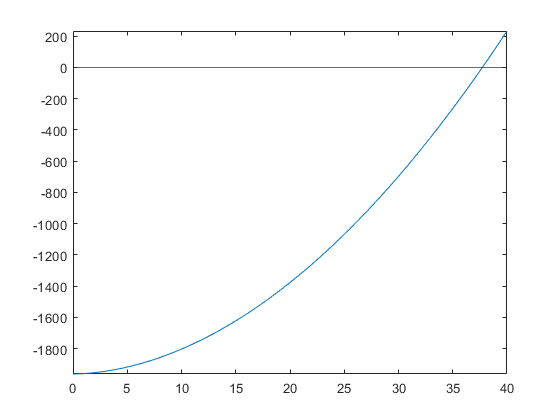

fplot(f, [0, 40])
yline(0)

[c, err, n] = bisect(f, 0, 40, 1e-5, 40)

c = 37.7347

err = 3.0518e-04

n = 17

err / c

ans = 8.0874e-06

clear
syms x

g = @(x) x + sqrt(1 ./ x) + .4 - 1.74 * log10(1e4 * sqrt(x));
g = @(x) real(g(x));
N = .316 * 1e-1

N = 0.0316

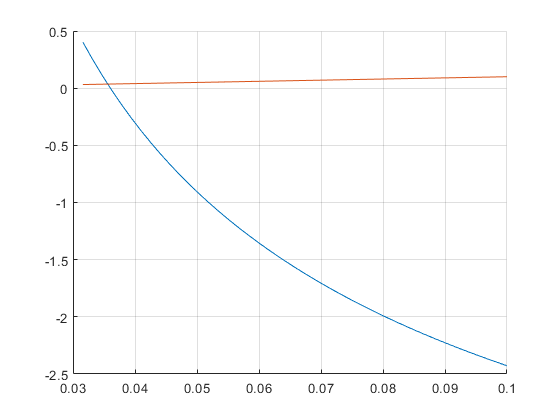

clf('reset')
hold on
fplot(g, [N, .1])
fplot(@(x) x, [N, .1])
grid on
hold off

[c, k, y] = fixpt(g, N, 1e-5, 20)

maximum number of iterations exceeded


c = -149.3124

k = 21

y = 8.4295

subs(diff(g, x), x, 2)

$$ans = 1-\frac{87}{200\,\log\left(10\right)}-\frac{\sqrt{2}}{8}$$

dg = @(x) 1 - (87*sign(x))/(100*log(sym(10))*abs(x)) - real(1/(x^2*sqrt(1/x)))/2;
eval(dg(N))

ans = -99.9670

t = 2;
t

t = 2

ans = logical
   1


clear
syms g(v_1, v_2) v_1 v_2

g(v_1, v_2) = 1.15*v_1^2 + 1.4*v_2^1.5 - 1962

$$g(v\_1, v\_2) = \frac{23\,{v_{1}}^{2}}{20}+\frac{7\,{v_{2}}^{3/2}}{5}-1962$$

g_1(v_2) = solve(g(v_1, v_2) == 0, v_1)

$$g\_1(v\_2) = \left(\begin{array}{c} -\frac{2\,\sqrt{23}\,\sqrt{9810-7\,{v_{2}}^{3/2}}}{23}\\ \frac{2\,\sqrt{23}\,\sqrt{9810-7\,{v_{2}}^{3/2}}}{23} \end{array}\right)$$

g_1(v_2) = (2*sqrt(sym(23))*sqrt(9810 - 7*v_2^sym(3/2)))/23

$$g\_1(v\_2) = \frac{2\,\sqrt{23}\,\sqrt{9810-7\,{v_{2}}^{3/2}}}{23}$$

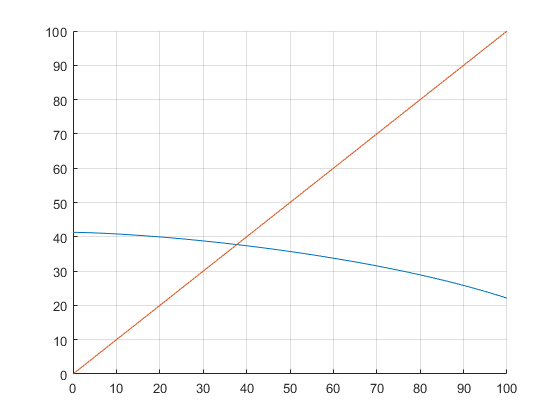

clf('reset')
hold on
fplot(g_1, [0, 100])
fplot(v_1, [0, 100])
hold off
grid on

dg_1(v_2) = diff(g_1, v_2);
eval(dg_1(38))

ans = -0.1493

c = fixpt(g_1, 40, 1e-5, 20)

c = 37.7346

clear
syms g(v_1, v_2) v_1 v_2

g(v_1, v_2) = 1.15*v_1^2 + 1.4*v_2^1.5 - 1962

$$g(v\_1, v\_2) = \frac{23\,{v_{1}}^{2}}{20}+\frac{7\,{v_{2}}^{3/2}}{5}-1962$$

g_2(v_1) = solve(g(v_1, v_2) == 0, v_2, 'Real', true)

$$g\_2(v\_1) = {\left(\frac{9810}{7}-\frac{23\,{v_{1}}^{2}}{28}\right)}^{2/3}$$

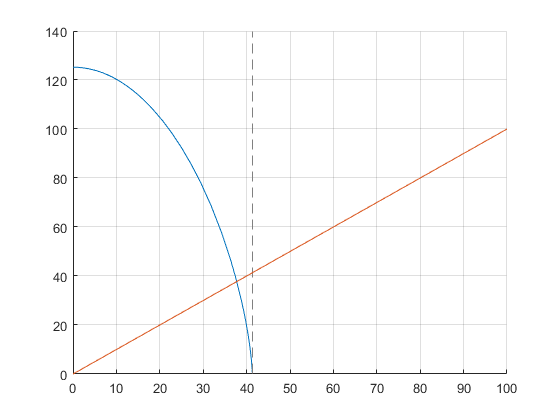

clf('reset')
hold on
fplot(g_2, [0, 100])
fplot(v_1, [0, 100])
hold off
grid on

dg_2(v_1) = diff(g_2, v_1);
eval(dg_2(37))

ans = -6.2174

c = fixpt(g_2, 40, 1e-5, 20)

maximum number of iterations exceeded


c = Inf + Infi

clear
syms g(v) 

g(v) = 1.15*v^2 + 1.4*v^1.5 - 1962

$$g(v) = \frac{23\,v^{2}}{20}+\frac{7\,v^{3/2}}{5}-1962$$

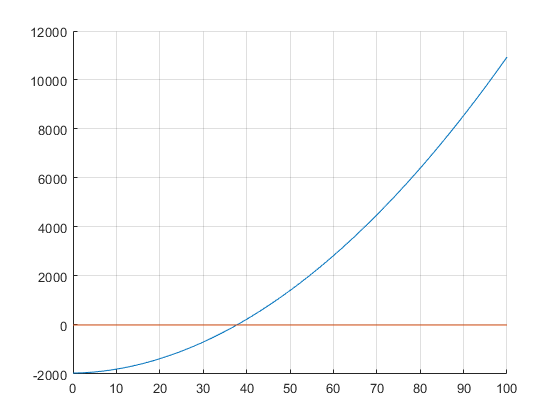

clf('reset')
hold on
fplot(g, [0, 100])
fplot(0, [0, 100])
hold off
grid on

dg(v) = diff(g, v);

%Procesamiento de las funciones
g = matlabFunction(g);
dg = matlabFunction(dg);

dg = function_handle with value:
    @(v)v.*(2.3e+1./1.0e+1)+sqrt(v).*(2.1e+1./1.0e+1)


c = newton(g, dg, 40, 1e-5, 1e-5, 20)

c = 37.7346

clear

A = [4 1 1 0 1;-1 -3 1 1 0; 2 1 5 -1 -1; -1 -1 -1 4 0; 0 2 -1 1 1]

A =      4     1     1     0     1
    -1    -3     1     1     0
     2     1     5    -1    -1
    -1    -1    -1     4     0
     0     2    -1     1     1


[J, GS, SOR] = Jac_GS(A, 1.5)

Radio Espectral


J =          0   -0.2500   -0.2500         0   -0.2500
   -0.3333         0    0.3333    0.3333         0
   -0.4000   -0.2000         0    0.2000    0.2000
    0.2500    0.2500    0.2500         0         0
         0   -2.0000    1.0000   -1.0000         0


GS =          0   -0.2500   -0.2500         0   -0.2500
         0    0.0833    0.4167    0.3333    0.0833
         0    0.0833    0.0167    0.1333    0.2833
         0   -0.0208    0.0458    0.1167    0.0292
         0   -0.0625   -0.8625   -0.6500    0.0875


SOR =    -0.5000   -0.3750   -0.3750         0   -0.3750
    0.2500   -0.3125    0.6875    0.5000    0.1875
    0.2250    0.3188   -0.4813    0.1500    0.4688
   -0.0094   -0.1383   -0.0633   -0.2562    0.1055
   -0.3984    1.6230   -2.6895   -0.8906   -0.5176


Punto 1. c)

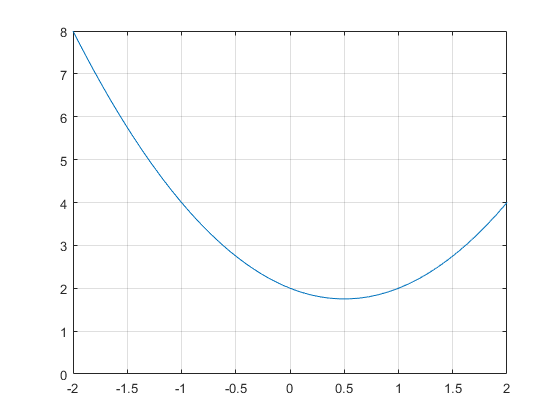

clear
syms f(x) p_n(p)

f(x) = x.^2 - x + 2; % Definimos la tercera función
df(x) = diff(f, x); % Definimos la primera derivada

fplot(f, [-2, 2])
yline(0)
grid on

### Asesoria 29/03/2022

Se resuelven dudas generales, y se revisa con los estudiantes los talleres.

clear
syms f(x) p

f(x) = exp(-2.5*x) * cos(5.5*x);
df(x) = diff(f, x);
% Definimos la iteración sucede que:
expr(p) = p - f(p) / df(p)

$$expr(p) = p+\frac{\cos\left(\frac{11\,p}{2}\right)\,{\mathrm{e}}^{-\frac{5\,p}{2}}}{\frac{5\,\cos\left(\frac{11\,p}{2}\right)\,{\mathrm{e}}^{-\frac{5\,p}{2}}}{2}+\frac{11\,\sin\left(\frac{11\,p}{2}\right)\,{\mathrm{e}}^{-\frac{5\,p}{2}}}{2}}$$

simplify(expr, 'Steps', 1)

$$ans(p) = \frac{2\,\cos\left(\frac{11\,p}{2}\right)+5\,p\,\cos\left(\frac{11\,p}{2}\right)+11\,p\,\sin\left(\frac{11\,p}{2}\right)}{5\,\cos\left(\frac{11\,p}{2}\right)+11\,\sin\left(\frac{11\,p}{2}\right)}$$